load tupleCount-MercuryErrorLog.txt

load tupling_MercuryErrorLog_200\interarrivals.txt

load tupleCount-BGLErrorLog.txt

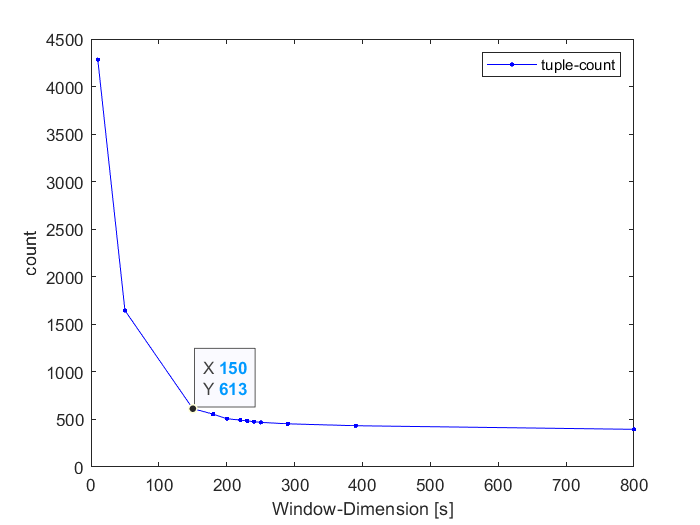

tpl_count_mrc = plot(tupleCount_MercuryErrorLog(:,1), tupleCount_MercuryErrorLog(:,2), '.-b');
xlabel('Window-Dimension [s]');
ylabel('count');
legend('tuple-count');
datatip(tpl_count_mrc, 150, 500);

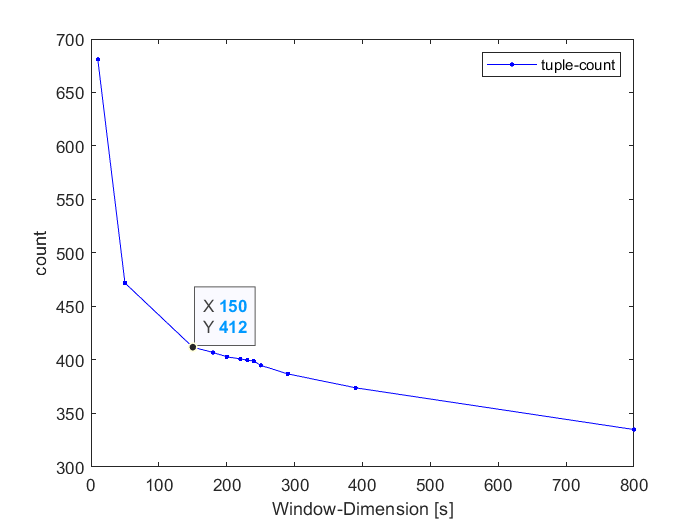

tpl_count_bgl = plot(tupleCount_BGLErrorLog(:,1), tupleCount_BGLErrorLog(:,2), '.-b');
xlabel('Window-Dimension [s]');
ylabel('count');
legend('tuple-count');
datatip(tpl_count_bgl, 150, 400);

load tupling_BGL-R12-Sensitivity-150\interarrivals.txt

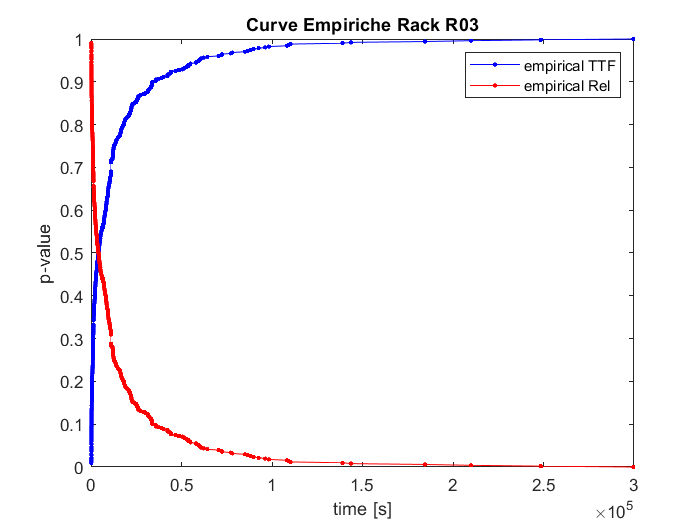

[y,t] = cdfcalc(interarrivals);
empTTF=y(2:size(y,1));
empRel=1-empTTF;
plot(t,empTTF,'.-b',t,empRel,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Rack R03')
legend('empirical TTF', 'empirical Rel');

[y,t62] = cdfcalc(interarrivals62);
empTTF=y(2:size(y,1));
empRel_R62=1-empTTF;

[y,t62] = cdfcalc(interarrivals62);
[y,t57] = cdfcalc(interarrivals57);
[y,t56] = cdfcalc(interarrivals56);
[y,t46] = cdfcalc(interarrivals46);
[y,t71] = cdfcalc(interarrivals71);
[y,t12] = cdfcalc(interarrivals12);
[y,t03] = cdfcalc(interarrivals03);

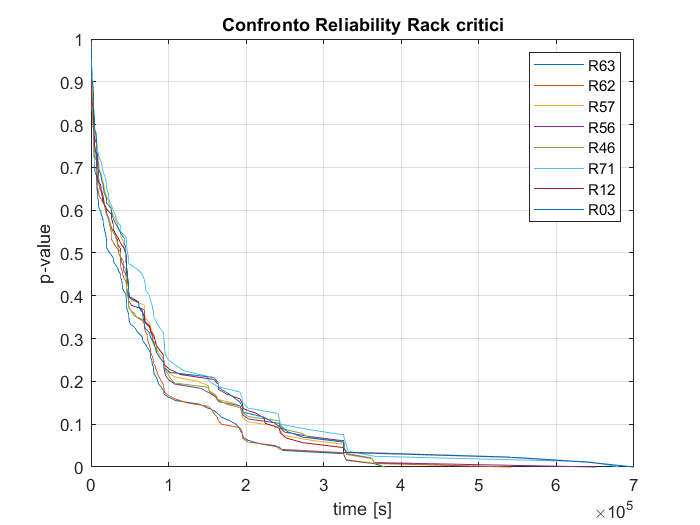

plot(t63,empRel_R63,t62, empRel_R62, t57, empRel_R57, t56, empRel_R56, t46, empRel_R46, t71, empRel_R71, t12, empRel_R12, t03, empRel_R03)
legend('R63','R62', 'R57', 'R56', 'R46', 'R71', 'R12', 'R03')
grid;
xlabel('time [s]');
ylabel('p-value');
title('Confronto Reliability Rack critici')

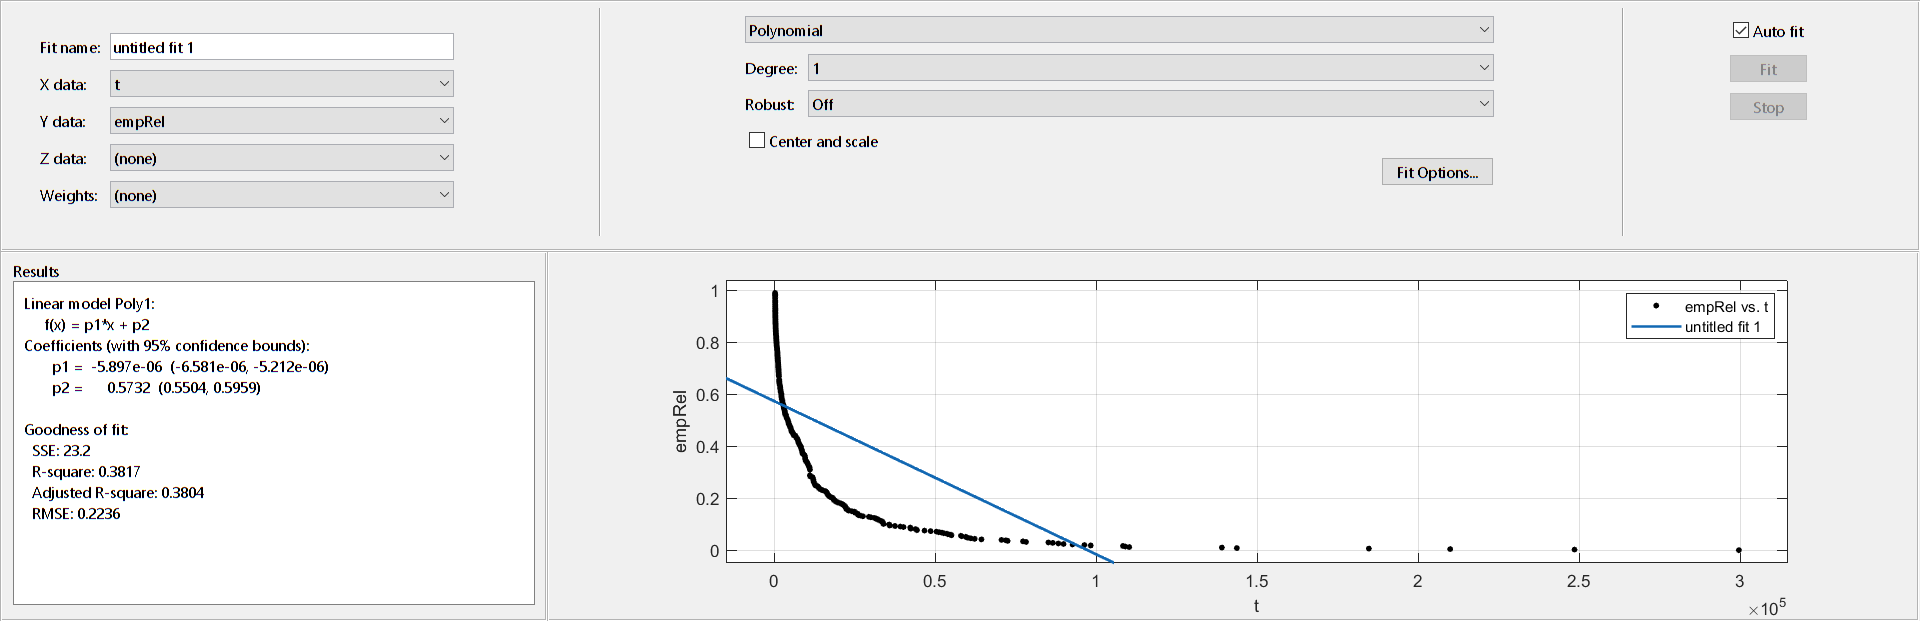

cftool(t,empRel)

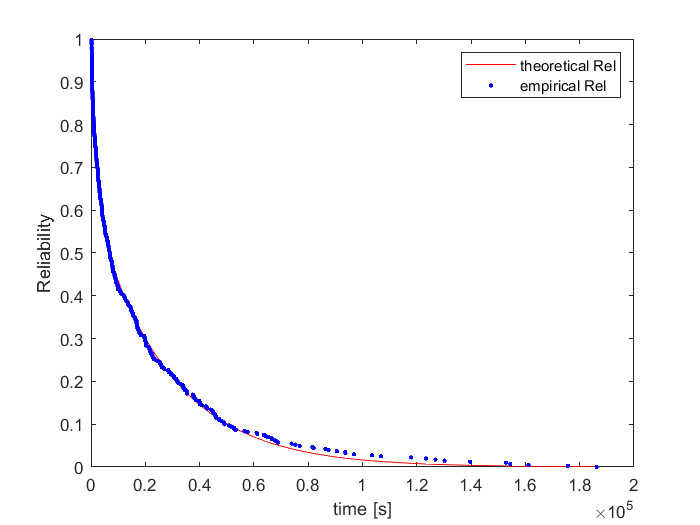

TTF_Exp = fit_BGL.a * exp(fit_BGL.b*t) + fit_BGL.c*exp(fit_BGL.d*t);

plot(t, TTF_Exp,'-r', t, empRel, '.b');
xlabel('time [s]')
ylabel('Reliability')
legend('theoretical Rel', 'empirical Rel')


[h,p,k] = kstest2(empRel,TTF_Exp, 'Alpha',0.05)

h = logical
   0


p = 0.8954

k = 0.0406

load tupling_MercuryComputation-300\interarrivals.txt

load tupling_MercuryLogin-300\interarrivals.txt

load tupling_MercuryMaster-300\interarrivals.txt

load tupling_MercuryStorage-150\interarrivals.txt

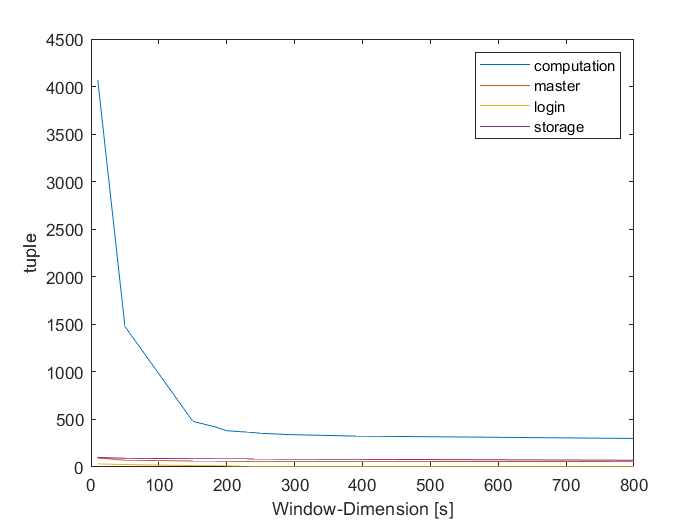


plot(comp(:,1), comp(:,2),master(:,1), master(:,2), login(:,1), login(:,2), storage(:,1), storage(:,2));
xlabel('Window-Dimension [s]');
ylabel('tuple');
legend('computation','master', 'login', 'storage');

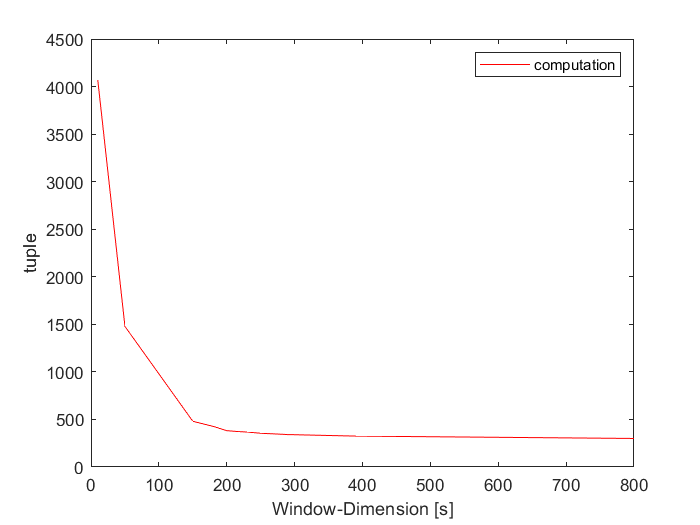

plot(comp(:,1), comp(:,2), 'r')
xlabel('Window-Dimension [s]');
ylabel('tuple');
legend('computation')

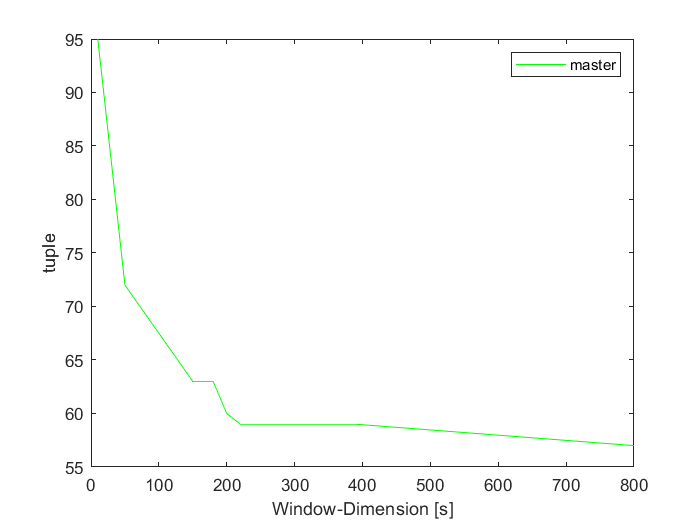

plot(master(:,1), master(:,2), 'g')
xlabel('Window-Dimension [s]');
ylabel('tuple');
legend('master')

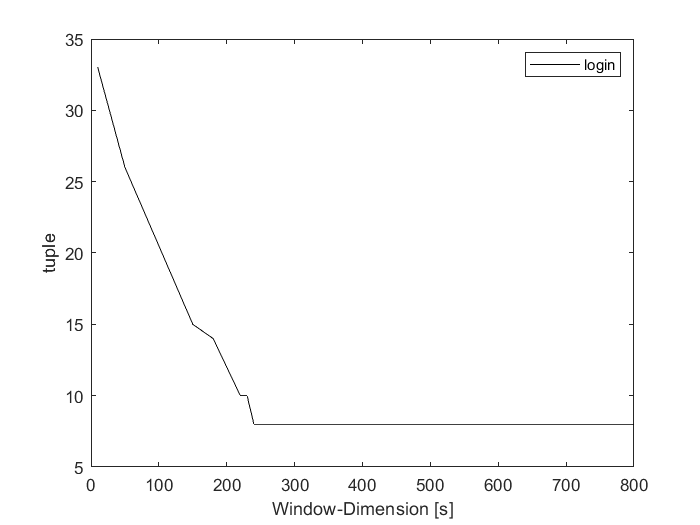

plot(login(:,1), login(:,2), 'k')
xlabel('Window-Dimension [s]');
ylabel('tuple');
legend('login')

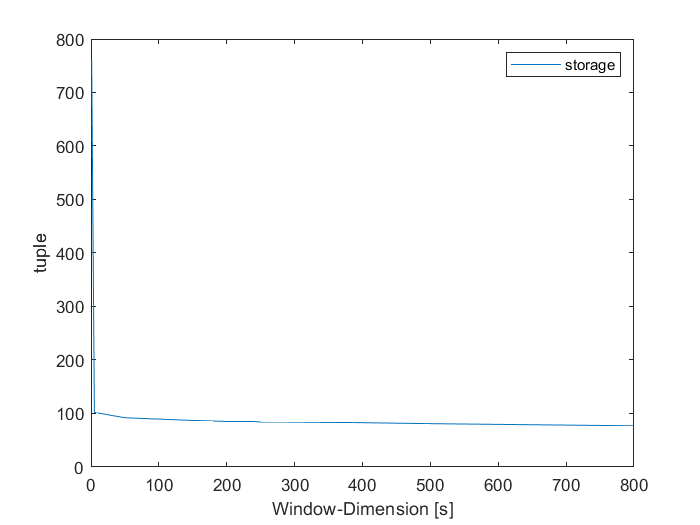

plot(storage(:,1), storage(:,2))
xlabel('Window-Dimension [s]');
ylabel('tuple');
legend('storage')

load tupling_MercuryErrorLog_200\interarrivals.txt

load tupling_BGLErrorLog_200\interarrivals.txt

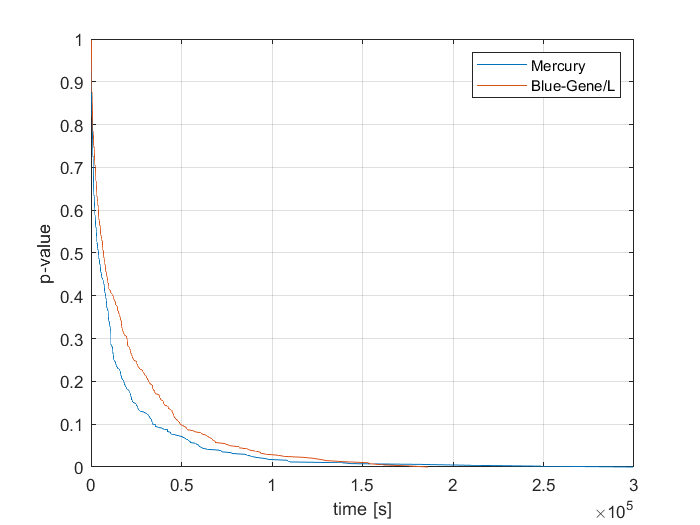

[yM,tM] = cdfcalc(interarrivalsMerc);
empTTF_Merc=yM(2:size(yM,1));
empRel_Merc=1-empTTF_Merc;
[yB,tB] = cdfcalc(interarrivalsBGL);
empTTF_BGL=yB(2:size(yB,1));
empRel_BGL=1-empTTF_BGL;
plot(tM, empRel_Merc, tB, empRel_BGL);
xlabel('time [s]');
ylabel('p-value');
legend('Mercury', 'Blue-Gene/L')
grid;

load tupleCount-BGL-error-computation.txt

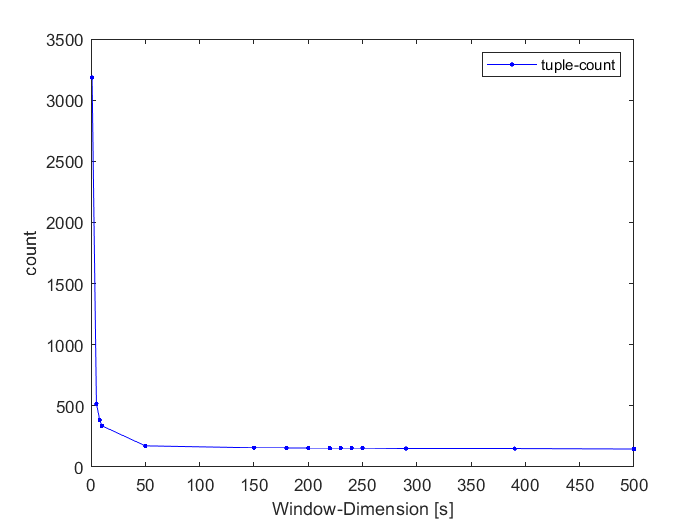

plot(tupleCount_BGL_error_computation(:,1), tupleCount_BGL_error_computation(:,2), '.-b');
xlabel('Window-Dimension [s]');
ylabel('count');
legend('tuple-count');

load tupling_BGL-error-computation-75\interarrivals.txt

load tupling_BGL-error-io-50\interarrivals.txt

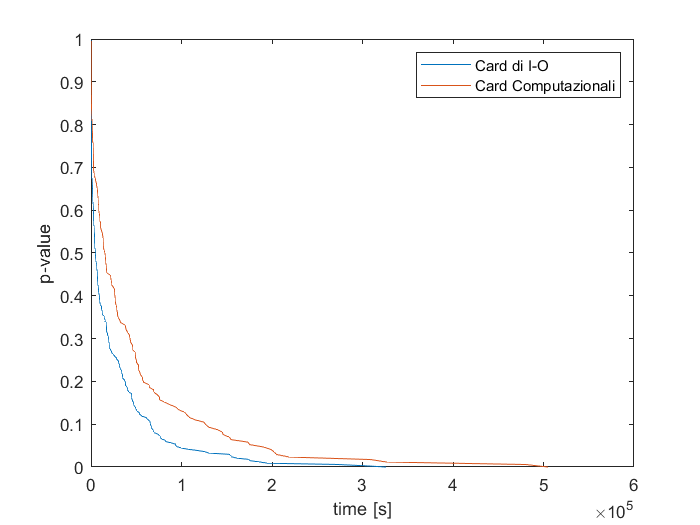

[yio,tio] = cdfcalc(interarrivals_io);
[ycomp,tcomp] = cdfcalc(interarrivals_com);

empTTF_io=yio(2:size(yio,1));
empRel_io=1-empTTF_io;

empTTF_comp=ycomp(2:size(ycomp,1));
empRel_comp=1-empTTF_comp;

plot(tio,empRel_io,tcomp,empRel_comp)
xlabel('time [s]')
ylabel('p-value')
legend('Card di I-O', 'Card Computazionali')

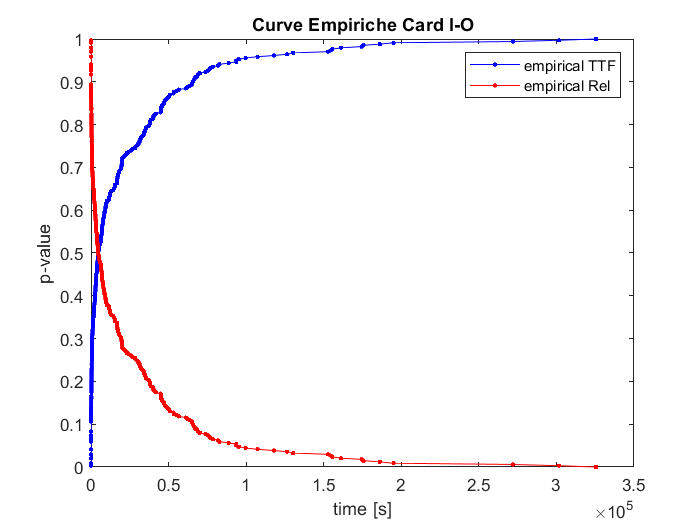



plot(tio,empTTF_io,'.-b',tio,empRel_io,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Card I-O')
legend('empirical TTF', 'empirical Rel');

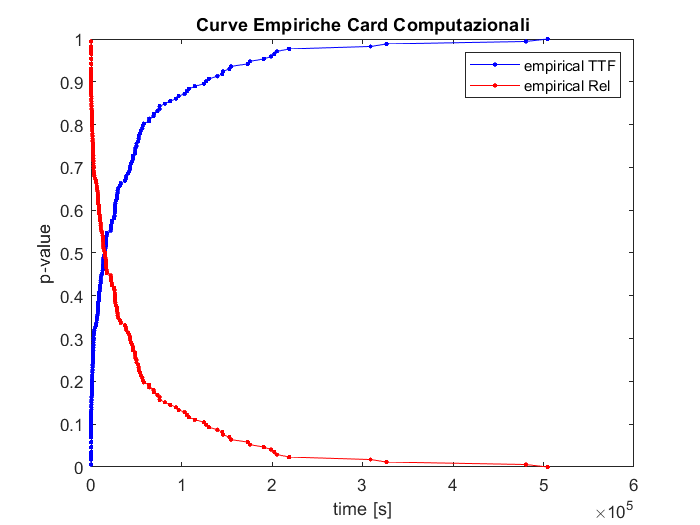


plot(tcomp,empTTF_comp,'.-b',tcomp,empRel_comp,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Card Computazionali')
legend('empirical TTF', 'empirical Rel');

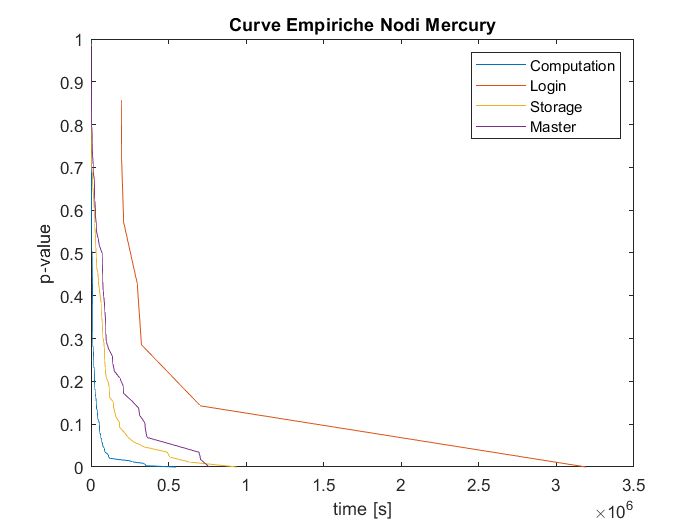

[yc,tc] = cdfcalc(int_comp);
empTTF_c=yc(2:size(yc,1));
empRel_c=1-empTTF_c;

[yl,tl] = cdfcalc(int_login);
empTTF_l=yl(2:size(yl,1));
empRel_l=1-empTTF_l;

[ym,tm] = cdfcalc(int_master);
empTTF_m=ym(2:size(ym,1));
empRel_m=1-empTTF_m;

[ys,ts] = cdfcalc(int_storage);
empTTF_s=ys(2:size(ys,1));
empRel_s=1-empTTF_s;

plot(tc,empRel_c, tl, empRel_l, ts, empRel_s, tm, empRel_m)
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Nodi Mercury')
legend('Computation', 'Login','Storage', 'Master')

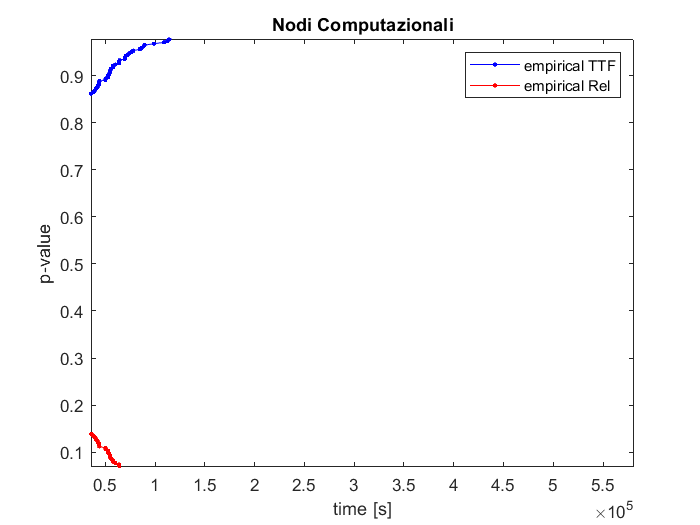


plot(tc,empTTF_c,'.-b',tc,empRel_c,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Nodi Computazionali')
legend('empirical TTF', 'empirical Rel');

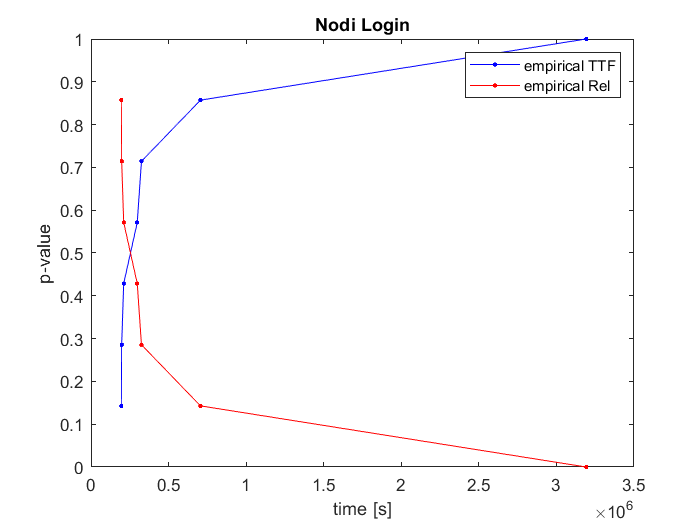


plot(tl,empTTF_l,'.-b',tl,empRel_l,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Nodi Login')
legend('empirical TTF', 'empirical Rel');

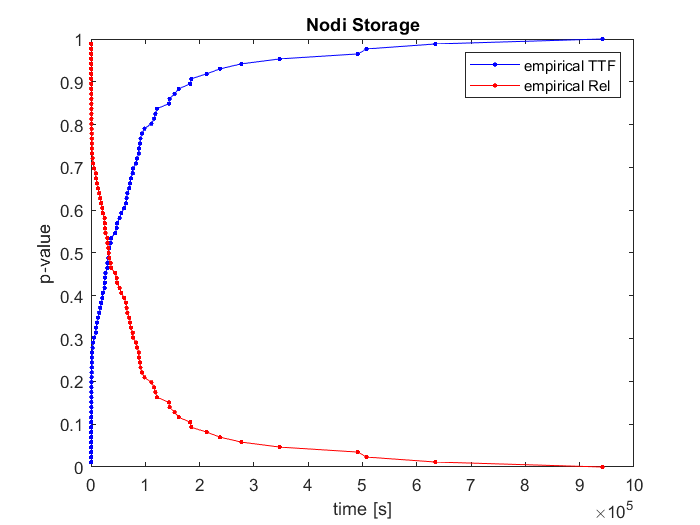


plot(ts,empTTF_s,'.-b',ts,empRel_s,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Nodi Storage')
legend('empirical TTF', 'empirical Rel');

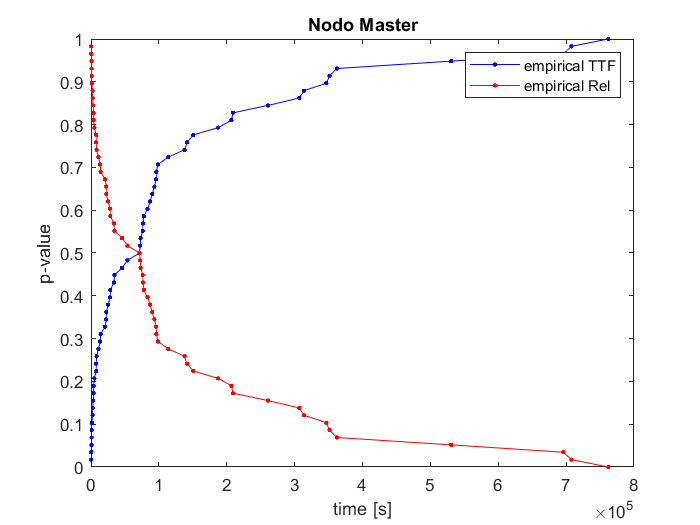


plot(tm,empTTF_m,'.-b',tm,empRel_m,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Nodo Master')
legend('empirical TTF', 'empirical Rel');

load tupling_MercuryErrorLog_200\interarrivals.txt

[y,t] = cdfcalc(interarrivals);
empTTF_merc=y(2:size(y,1));
empRel_merc=1-empTTF_merc;

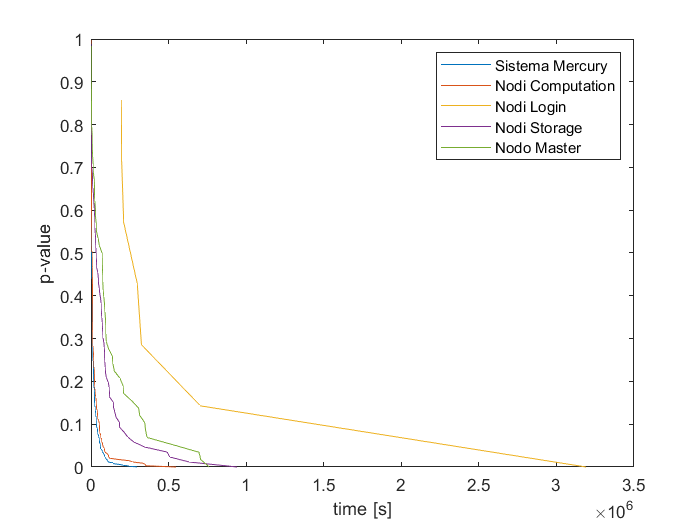


plot(t,empRel_merc, tc,empRel_c, tl, empRel_l, ts, empRel_s, tm, empRel_m)
xlabel('time [s]'); ylabel('p-value');
legend('Sistema Mercury', 'Nodi Computation', 'Nodi Login', 'Nodi Storage', 'Nodo Master');

load tupling_tg-c401-MercuryErrorLog-200\interarrivals.txt

[yc401,tc401] = cdfcalc(interarrivalsc401);
empTTF_c401=yc401(2:size(yc401,1));
empRel_c401=1-empTTF_c401;

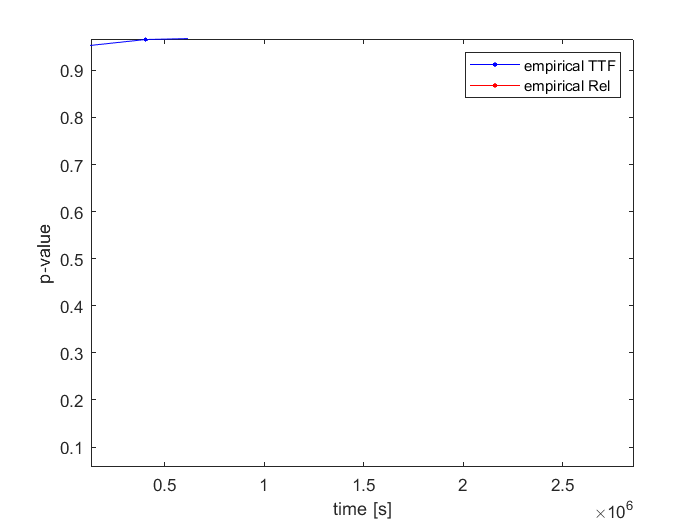


plot(tc401,empTTF_c401,'.-b',tc401,empRel_c401,'.-r');
xlabel('time [s]'); ylabel('p-value'); 
legend('empirical TTF', 'empirical Rel');

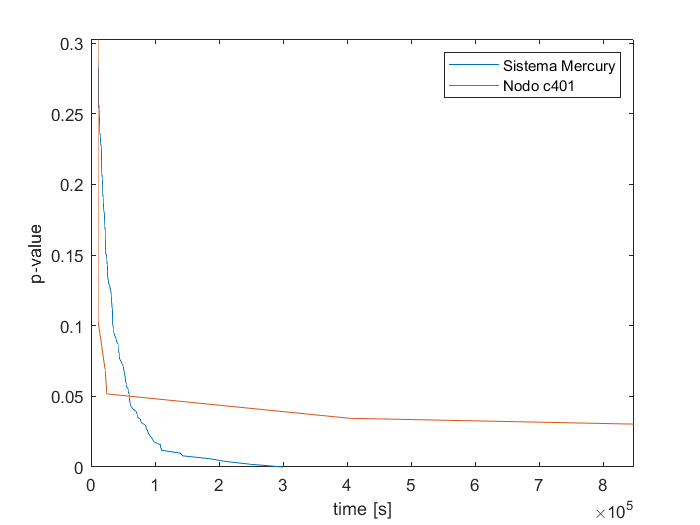

plot(t,empRel_merc, tc401, empRel_c401)
xlabel('time [s]'); ylabel('p-value');
xlim([0 848066])
ylim([0.000 0.303])
legend('Sistema Mercury', 'Nodo c401')